% Paso 1: Pedir los valores de los puntos
n = input('Número de puntos: '); % Número de puntos

X = zeros(n, 1); % Inicializar vector de X
Y = zeros(n, 1); % Inicializar vector de Y

for i = 1:n
    X(i) = input(['X(' num2str(i) '): ']);
    Y(i) = input(['Y(' num2str(i) '): ']);
end

% ---------- MODELO EXPONENCIAL ----------
% Verificar si Y contiene valores mayores que 0 (para evitar logaritmo de 0 o negativos)
if any(Y <= 0)
    error('Todos los valores de Y deben ser positivos para el modelo exponencial.');
end

% Tomar el logaritmo de Y para convertirlo en un modelo lineal
Y_log = log(Y); % logaritmo natural de Y

% Construir la matriz A para el modelo exponencial
A_exponencial = [ones(n, 1), X]; % Matriz con columna de unos y valores de X

% Calcular la fórmula de ajuste para el modelo exponencial
At_exponencial = A_exponencial'; % Transpuesta de A_exponencial
AtA_exponencial = At_exponencial * A_exponencial; % A' * A
AtA_inv_exponencial = inv(AtA_exponencial); % Inversa de (A' * A)
AtY_exponencial = At_exponencial * Y_log; % A' * log(Y)
u_exponencial = AtA_inv_exponencial * AtY_exponencial; % Coeficientes de la recta

% Obtener los coeficientes del modelo exponencial
a_exp = exp(u_exponencial(1)); % a = exp(intercepto)
b_exp = u_exponencial(2); % b es la pendiente

% Mostrar los coeficientes
disp('Coeficientes de la ecuación exponencial:');

Coeficientes de la ecuación exponencial:


disp(['a (base): ' num2str(a_exp)]);

a (base): 8.9443


disp(['b (exponente): ' num2str(b_exp)]);

b (exponente): -0.57683



% Evaluar Y_hat para el modelo exponencial
Y_hat_exponencial = a_exp * exp(b_exp * X);

% Cálculo del ECM para el modelo exponencial
ECM_exponencial = sum((Y - Y_hat_exponencial).^2) / n;

% Mostrar el ECM
disp(['Error Cuadrático Medio (ECM) - Modelo Exponencial: ' num2str(ECM_exponencial)]);

Error Cuadrático Medio (ECM) - Modelo Exponencial: 1.5368


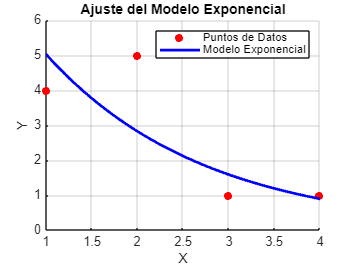


% ---------- GRAFICAR RESULTADOS ----------
% Crear una figura
figure;

% Graficar los datos originales
scatter(X, Y, 'ro', 'filled', 'DisplayName', 'Puntos de Datos');
hold on;

% Crear un rango de X para graficar la función exponencial ajustada
X_plot = linspace(min(X), max(X), 100)';
Y_plot = a_exp * exp(b_exp * X_plot);

% Graficar la curva exponencial ajustada
plot(X_plot, Y_plot, 'b-', 'LineWidth', 2, 'DisplayName', 'Modelo Exponencial');
xlabel('X');
ylabel('Y');
title('Ajuste del Modelo Exponencial');
legend('show');
grid on;